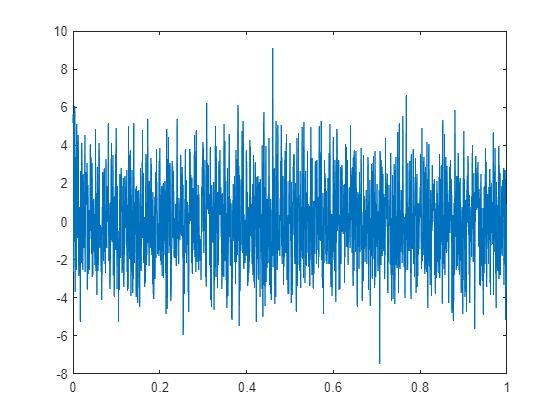

% Create the input signal.
Fs = 2000;
N = 2000;
rng default;
t = (0:N-1)/Fs;
x = (cos(100*2*pi*t) + randn(1, N)) + (cos(250*2*pi*t) + randn(1, N)) + (cos(500*2*pi*t) + randn(1, N));
plot(n, x)

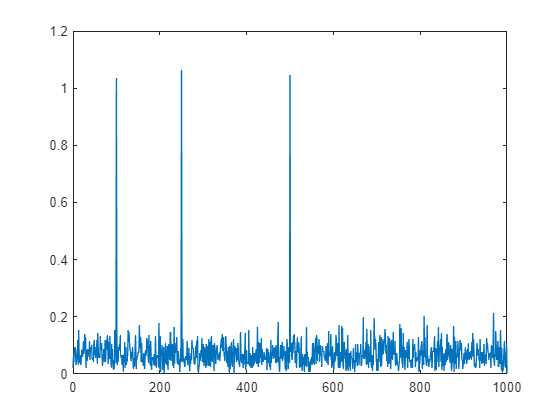

% Look at the frequency content of the signal.
X = fft(x);
P2 = abs(X/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;
plot(f, P1);

axis()

ans = 1.0e+03 *

         0    1.0000         0    0.0012


% Design a passband filter
%df = designfilt('passbandfir', 'FilterOrder', 40, 'CutoffFrequency1', 400, 'CutoffFrequency2', 600, 'SampleRate', Fs);
df = designfilt('bandpassfir','FilterOrder',10, ...
         'CutoffFrequency1',400,'CutoffFrequency2',600, ...
         'SampleRate',Fs);
hfvt = fvtool(df);

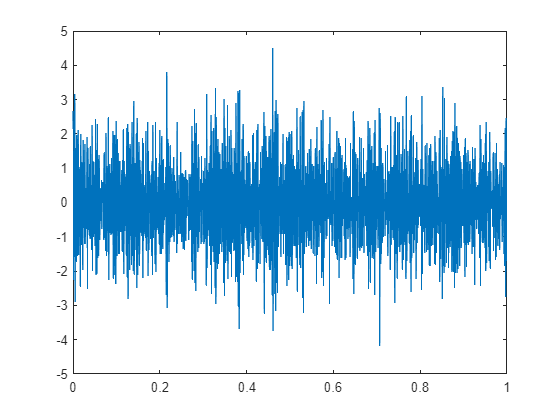

D = mean(grpdelay(df));
y = filter(df, [x zeros(1, D)]);
y = y(D+1:end);
plot(t, y);

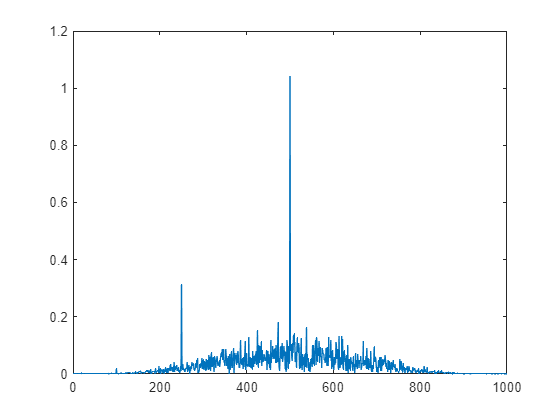

% Look at the frequency content of the signal.
Y = fft(y);
P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;
plot(f, P1);

axis()

ans = 1.0e+03 *

         0    1.0000         0    0.0012
